# Weighted audio filters

(Moved from original project due to time limitations)

Les filtres Statiques nous ont permis de nous rendre à bonne qualité de signal. Cependant, l'oreille humaine est considéré comme étant un transducteur non-linérair 

En regardant il est évident que le bruit étouffé à l'oreil provient du manque de richesse fréquencielle du son sortant du filtre passe bande.

Ceci étant les meuilleurs résultats avec les filtres statiques.

Dans ce cas ci l'utilisation d'implémntation différentes telles que Chebycheve ou butterworth, ont des résultats qui ne sont pas perceptibles à l'oreille. 

Passons maintenant à des filtres dynamiques ou adaptatifs

A and C Weighting (ANSI® S1.42 Standard)

You can design A and C weighting filters that follow the ANSI S1.42 [1] and IEC 61672-1 [2] standards using weightingFilter System object. An A-weighting filter is a bandpass filter designed to simulate the perceived loudness of low-level tones. An A-weighting filter progressively de-emphasizes frequencies below 500 Hz. A C-weighting filter removes sounds outside the audio range of 20 Hz to 20 kHz and simulates the loudness perception of high-level tones. The following code designs an IIR filter for A-weighting with a sampling rate of 48 kHz.

AWeighting = weightingFilter('A-weighting',sampleRate);

https://www.mathworks.com/help/simulink/ug/tutorial-integrating-matlab-code-with-a-simulink-model-for-filtering-an-audio-signal.html

## mean filtering

windowSize = 1500;
b = (1/windowSize)*ones(1,windowSize);
a = 1;

meanFilterResults = filter(b,a,son_1_avec_perturbation);

plot(sample_point,meanFilterResults);

## AutoCorrelation TRY 2

## Adaptative try 1

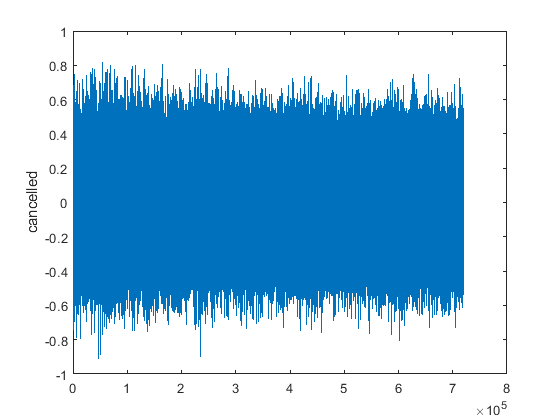


refer = cropped_sound;
primary = son_1_avec_perturbation;

order=2;
mu=0.00005;

n=length(cropped_sound);
delayed=zeros(1,order);
adap=zeros(1,order);
cancelled=zeros(1,n);

for k=1:n,
    delayed(1)=refer(k);
    y=delayed*adap';
    cancelled(k)=primary(k)-y;
    adap = adap + 2*mu*cancelled(k) .* delayed;
    delayed(2:order)=delayed(1:order-1);
end

plot(sample_point,cancelled);
ylabel('cancelled');
hold on;


%% Adaptative usng weiner correlation based filter

## réduction par réduction https://www.mathworks.com/matlabcentral/answers/502059-remove-white-noise-after-adding-it-with-awgn-by-spectral-substraction-method

% Mute values less than 0.1
% Get indexes where the signal is soft or quiet.
quietIndexes =  trans_bruit2 < 0.1; % Whatever.
signal(quietIndexes) = 0; % Apply muting
sound(quietIndexes,sampleRate);

% voir : https://www.mathworks.com/help/dsp/ref/dsp.lmsfilter-system-object.html


% https://www.mathworks.com/help/dsp/examples/adaptive-line-enhancer-ale.html



Dans ce ca ci les filtres highpass et coupe bande ne seront pas utiles pour le cas de l'isolation d'une voix humaine. Ces filtre ne seront donc pas utilisé pour fin de la pertinece des démarches. Afin d'éviter les répetitions essayons des nouveau types de filtes. les filtres adaptatifs. 

## Least Mean Square (LMS)

Les filtrs LMS sont reconnues comme utilisant les algorithmes les plus simples des filtres adaptatifs. Aussi connue comme étant les filtres Weiner, ils sont particulièrement utiles dans le cas de Systemes Linéaires et Invariant das le temps. Ils sont doncs utiles avec des sytemes causals. 

En résumé : ils utilisenet un algorithme d'autorégression afin de calculer l'erreur sur la variance au carré des valeurs du signal.

                                                            
$$J=E\left(e\left\lbrack n\right\rbrack {\left.\right)}^2 \right)\;$$


$e\left\lbrack n\right\rbrack =d\left\lbrack n\right\rbrack -\sum_{k=0} h\left\lbrack k\right\rbrack \;\;x\left\lbrack \;n-k\right\rbrack$ ## mettre figure 

[https://www.youtube.com/watch?v=BM7i8LHFwyY](https://www.youtube.com/watch?v=BM7i8LHFwyY) 